clear all
close all
clc

%nome del gruppo e membri
% Fares Peter William – 721654
% Mirandola Edoardo – 723993
% Pennacchio Manuele – 721965
nome_gruppo = 'GruppoG';

%aggiunta dei path dove sono i modelli e i controllori
%addpath("controllori")
addpath("modello")

load("file_mat_init\ctrl1.mat")
load("file_mat_init\ctrl2.mat")

%definizione del sistema
system=ElasticRoboticSystem();
st=system.getSamplingPeriod;

%definizione dei controllori
cs=ControlledSystemScara(system,nome_gruppo);

Tf1_pos = 1000;
Tf2_pos = 1000;
ctrl = CascadeController(st,@idynRigid,...
                Kp1_pos,Ki1_pos,Kp1_vel,...
                Kp2_pos,Ki2_pos,Kp2_vel,...
                Wn_notch1,xci_z1,xci_p1,...
                Wn_notch2,xci_z2,xci_p2,...
                Tf1_pos,Tf1_vel,...
                Tf2_pos,Tf2_vel);

ans =   PI_pos_FPB with properties:

          Kp: 144.6271
          Ki: 0.0106
      u_past: 0
      e_past: 0
          Ti: 1.3702e+04
        UMax: []
          Tf: 1000
     UinPast: 0
    UoutPast: 0
          Fs: []
          Fd: []
           j: 5.0000e-07
           k: 5.0000e-07
           l: 1
           m: -1.0000
        u_m1: 0
       un_m1: 0

ans =   PI_vel_FBP_FN with properties:

           Kp: 3.4092e+03
         UMax: []
           wn: 665
        xci_p: 0.7000
        xci_z: 0.1500
           Tf: 1.0000e-03
            j: 0.3333
            k: 0.3333
            l: 1
            m: -0.3333
            a: 0.7679
            b: -1.1287
            c: 0.6414
            d: 1
            f: -1.1287
            g: 0.4093
         u_m1: 0
         u_m2: 0
    unotch_m1: 0
    unotch_m2: 0
        un_m1: 0
        un_m2: 0

ans =   PI_pos_FPB with properties:

          Kp: 175.7173
          Ki: 0.0218
      u_past: 0
      e_past: 0
          Ti: 8.0455e+03
        UMax: []
          Tf: 1000
     UinPast: 0
    UoutPast: 0
          Fs: []
          Fd: []
           j: 5.0000e-07
           k: 5.0000e-07
           l: 1
           m: -1.0000
        u_m1: 0
       un_m1: 0

ans =   PI_vel_FBP_FN with properties:

           Kp: 1.8294e+03
         UMax: []
           wn: 986.8000
        xci_p: 0.7000
        xci_z: 0.2000
           Tf: 1.0000e-03
            j: 0.3333
            k: 0.3333
            l: 1
            m: -0.3333
            a: 0.7449
            b: -0.7823
            c: 0.5408
            d: 1
            f: -0.7823
            g: 0.2857
         u_m1: 0
         u_m2: 0
    unotch_m1: 0
    unotch_m2: 0
        un_m1: 0
        un_m2: 0


cs.setController(ctrl);

ans =   CascadeController with properties:

      PI1pos_Fpb: [1×1 PI_pos_FPB]
    P1vel_Fpb_Fn: [1×1 PI_vel_FBP_FN]
      PI2pos_Fpb: [1×1 PI_pos_FPB]
    P2vel_Fpb_Fn: [1×1 PI_vel_FBP_FN]
           model: @idynRigid

cs.initialize
%settaggio dei parametri di massima accellerazione e di rest time
max_acc=2;
rest_time=0.05;
cs.setMaxAcceleration(max_acc);
cs.setRestTime(rest_time);
% cambia punto di lavoro
cs.moveTo([0 0]);

% simulo il sistema per la valutazione
% "fast" fa 5 esecuzioni
% "complete" fa 5 x 5 esecuzioni (modalità esame)
tic
[score,results]=cs.evalution("fast");

iteration 1, score = -11048.506523
iteration 2, score = -5163.285001
iteration 3, score = -8276.994662
iteration 4, score = -6637.847512
iteration 5, score = -7501.088726


computation_time=toc;
simulated_time=sum([results.Ttot]);
fprintf('Real-time factor = %f\n',simulated_time/computation_time)

Real-time factor = 0.988339


warning off
% grafico i risultati
fprintf('lo score è %f\n',score);

lo score è -7725.544485


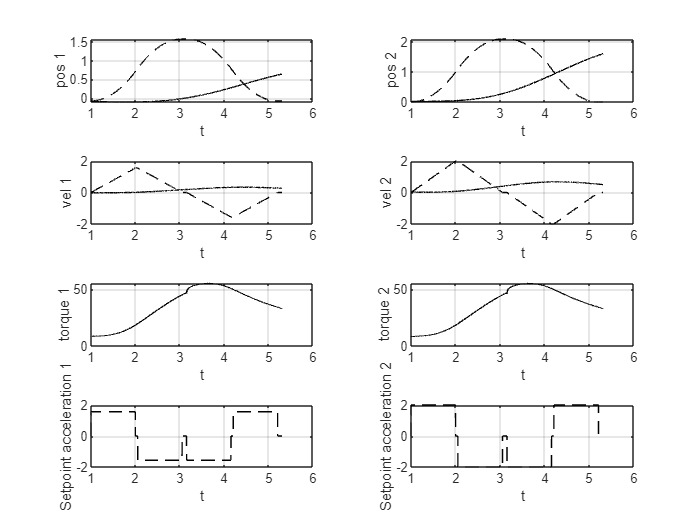

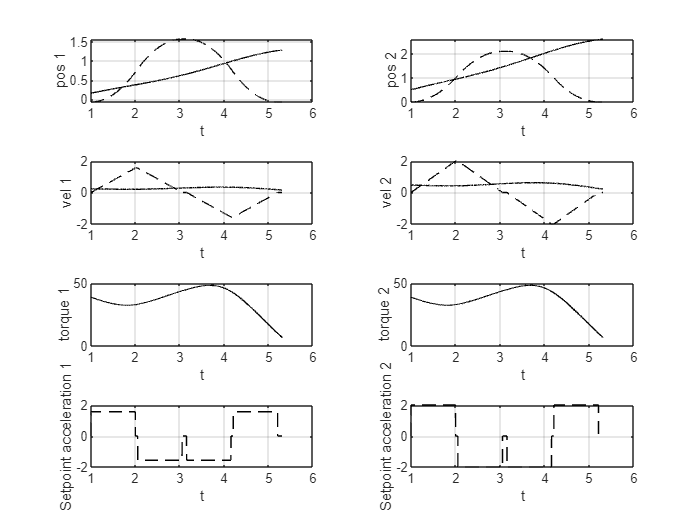

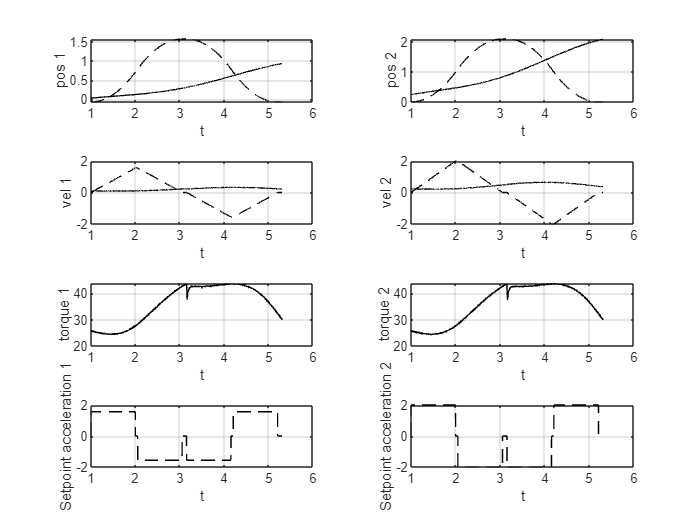

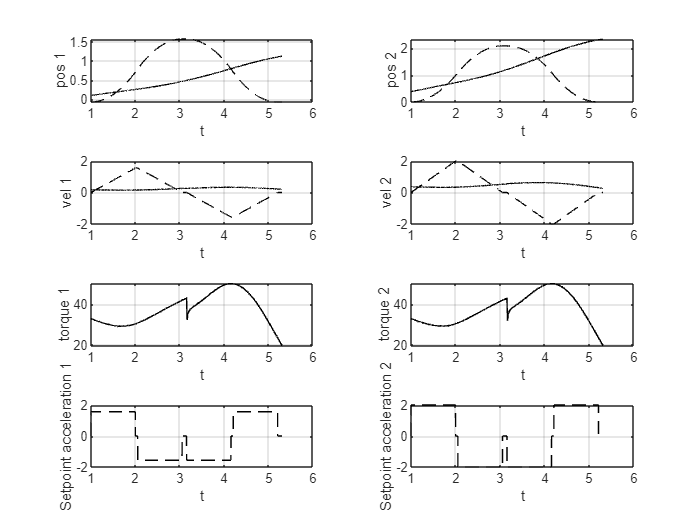

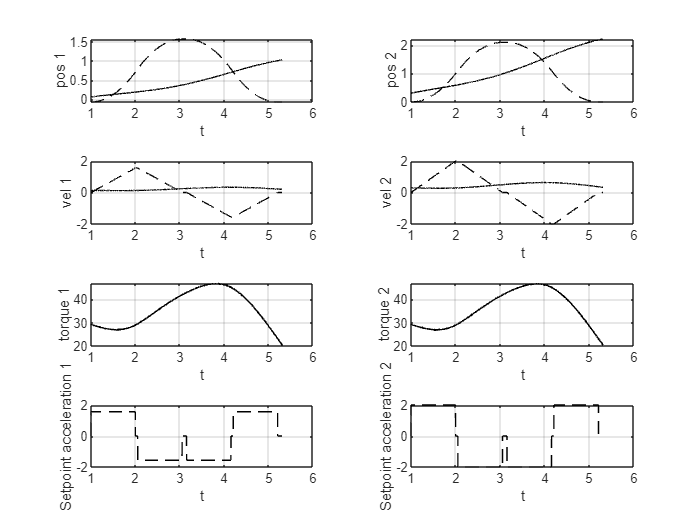

cs.showResults(results)